# BME 2740 Interactive Lecture 12

# By: Dr. Asad Mirza

# Adapted From: Dr. Ilmar Tamames

## Euler’s Method of Integration 

#### Example 1

Unconstrained population growth of bacteria is governed by the following equation:


$$\frac{\textrm{dP}}{\textrm{dt}}=\textrm{rP}$$


where P is population size, t is time, and r is a positive constant.

Using separation of variables:


$$\frac{\textrm{dP}}{P}=\textrm{rdt}$$


Integrating both sides:


$$\int \frac{\textrm{dP}}{P}=\int \textrm{rdt}$$



$$\ln \left(P\right)=\textrm{rt}+C$$


Raising to the power of e:


$$e^{\ln \left(P\right)\;} =e^{\left(\textrm{rt}+c\right)} =e^{\textrm{rt}} e^c ={\textrm{Ce}}^{\textrm{rt}}$$



$$P=Ce^{\textrm{rt}}$$


Where constant C is your initial population P(0).

If the initial population is 1000 members 


$$P\left(0\right)=C{\;e}^{r*0} =1000$$



$$C=1000$$


If we also knew that at t=1 the population is 2000:


$$P\left(1\right)=1000{\;e}^{r*1} =2000$$



$$1000{\;e}^r =2000$$



$${\;e}^r =2$$



$$r=\ln \left(2\right)$$


Then:


$$P\left(t\right)=1000\;e^{\ln \left(2\right)*t} =1000\;te^{\ln \left(2\right)} =1000t*2=2000t$$


Suppose we did not know the solution: how could we evaluate the function $\frac{\textrm{dP}}{\textrm{dt}}=\textrm{rP}$ with an initial value of P(0)=1000 and a known value of r?

### Forward Euler’s Method of Integration 

We already know a way to approximate a function at a given point using the Taylor Series, and last class we used this information to deduce an approximation of that function's first derivative:


$$f^{\prime } \left(a\right)=f^{\left(1\right)} \left(a\right)\cong \frac{f{\left(a+h\right)}-f{\left(a\right)}}{h}$$


If we then take a small step, h, in the tangential direction of y and find another Taylor Series approximation at *a+1*, we can begin a chain of approximations.

1. Set initial condition.

2. Assume the derivative of the solution function, *f(t,y)*, is constant over an interval *h*:


$$f^{{\left(1\right)}} {\left(a\right)}\cong \frac{f{\left(a+h\right)}-f{\left(a\right)}}{h}$$


Our derivative is usually given to use as a function of t (independent variable) but it can also be with respect to y for implicit equations. Also, don't be confused if you just have data points to work with instead, you can treat them as discrete values of $f\left(t_k ,y_k \right)$ with a fixed $h$.


$$f^{{\left(1\right)}} {\left(a\right)}=f\left(t_k ,y_k \right)$$



$$f\left(t_k ,y_k \right)=\frac{y_{k+1} -y_k }{h}$$



$$y_{k+1} =y_k +f{\left(t_k ,y_k \right)}h$$


3. Iteratively compute $y_{k+n}$ for n successive values of $t_k$.

This is the essence of numerical approximation to differential equations. 

**We discretize our differential equation using a given integration method, in this case Forward Euler, and solve them one step at a time.**

Note the recursive aspect of the method, we know $y_k$ on the first loop, we then know what $y_{k+1}$is for the second loop, we then know what $y_{k+2}$ is for the third loop, and so on and so forth.

####  Back to example 1

1.Set initial condition

P(0)=1000, P(1)=2000

2. Assume the derivative of the solution function, f(t,y), is constant over an interval h: 


$$y_{k+1} =y_k +f{\left(t_k ,y_k \right)}h$$


Step size h =.5 to start.

3. Iteratively compute $y_{k+n}$ for n  successive values of $t_k$.

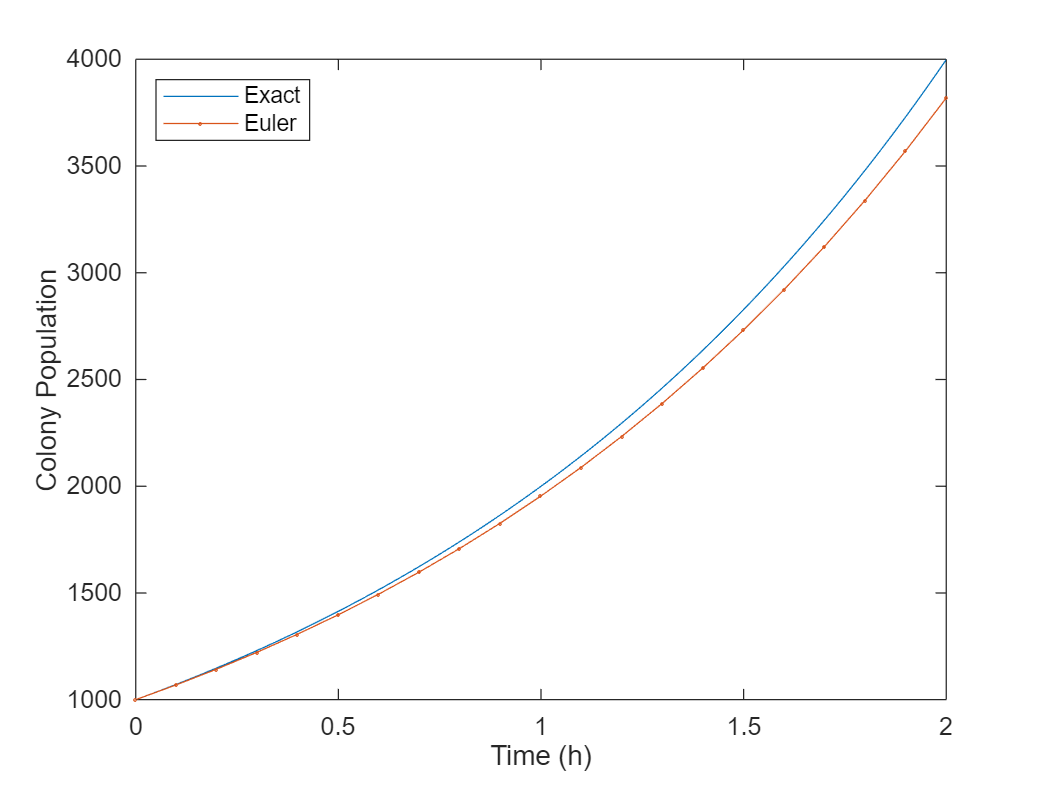

% Solve dP/dt = rP  % << This is the equation
% Initial condition: P(0)=1000
% >> When t = 0, Population is 1000.
% >> When t = 1, Population is 2000.

P0 = 1000;       % Initial condition
r = 0.693;     % Known time constant log(2)
h = 0.1;        % Step size, try .2,.1,.01

% Stepwise descibes how fowards in r to move with each calc. Smaller
% usually better but will require more calculations so more procesisng
% power.

tfinal = 2;  % Final Time, stop here
t = 0:h:tfinal;


% Forward Euler Loop, for all time points except the last.

P = zeros(size(t));     % Preallocate memory for approximate solution
% creates an array filled with zeros to store the population estimates.


P(1) = P0;              % Apply initial condition P(0) but for us 0 is the first element, 1

% Euler uses this formula
% New Value = Old Value + (Derivative * h)

% In our case, one method is P_new = P_old + r*P_old*h

for ii=1:length(t)-1 % he -1 is there because the loop calculates the next value, P(ii+1), 
% so it must stop before it runs out of values in the array.
    % The new value of p(t) is equal to the old value plus (dP/dt)*h
    % Remember: dp/dt = f(t,y) = rP
    P(ii+1) = P(ii) + r*P(ii)*h;
end


% Plotting
tt = linspace(0,tfinal);
y=P0*exp(r*tt);
plot(tt,y) % Exact solution
hold on
plot(t,P,'-o','markersize',1)
hold off
ylabel("Colony Population");
xlabel("Time (h)");
legend('Exact','Euler',"Location","northwest")

**The power of what we have just done is incredible: we have turned a differential equation into an algebra problem, **$y_{k+1} =y_k +f{\left(t_k ,y_k \right)}h\approx y=b+\textrm{mx}$

#### Example 2

New research published in the journal, *DNA*, has demonstrated that the stability of base-pairs of synthetic DNA made with phosphoramidite decays according to the following equation:


$$\frac{dS\left(t\right)}{dt}+2S{\left(t\right)}=cos{\left(4t\right)}$$


Your new startup company, The Genie’s Genes Inc., is using phosphoramidite procedures to edit animal genomes to mitigate various genetic diseases. This new study shows you must account for the loss of stability, S, over time, t. To do this, you must know the decay in stability over time. Your synthesis procedure takes 4 hours and begins with a concentration of S(0)=1. Show the absolute error of the above approximation at S(2).

Remember that we can approximate the first derivative using the Forward Euler Method


$$f\left(t_k ,y_k \right)=\frac{y_{k+1} -y_k }{h}$$


Discretize our differential equation:


$$\frac{\left(S_{i+1} -S_i \right)}{h}+2S_i =cos{\left(4t_i \right)}$$


Solve for $S_{i+1}$


$$S_{i+1} =S_i +h*\left(\cos {\left(4t_i \right)}-2S_i \right)$$


Notice how $\left(\cos {\left(4t_i \right)}-2S_i \right)$ is just our$f{\left(t_k ,y_k \right)}$


$$S_{i+1} =S_i +h*f\left(t_i ,S_i \right)$$


This form always works so long as your ODE is 1st order.

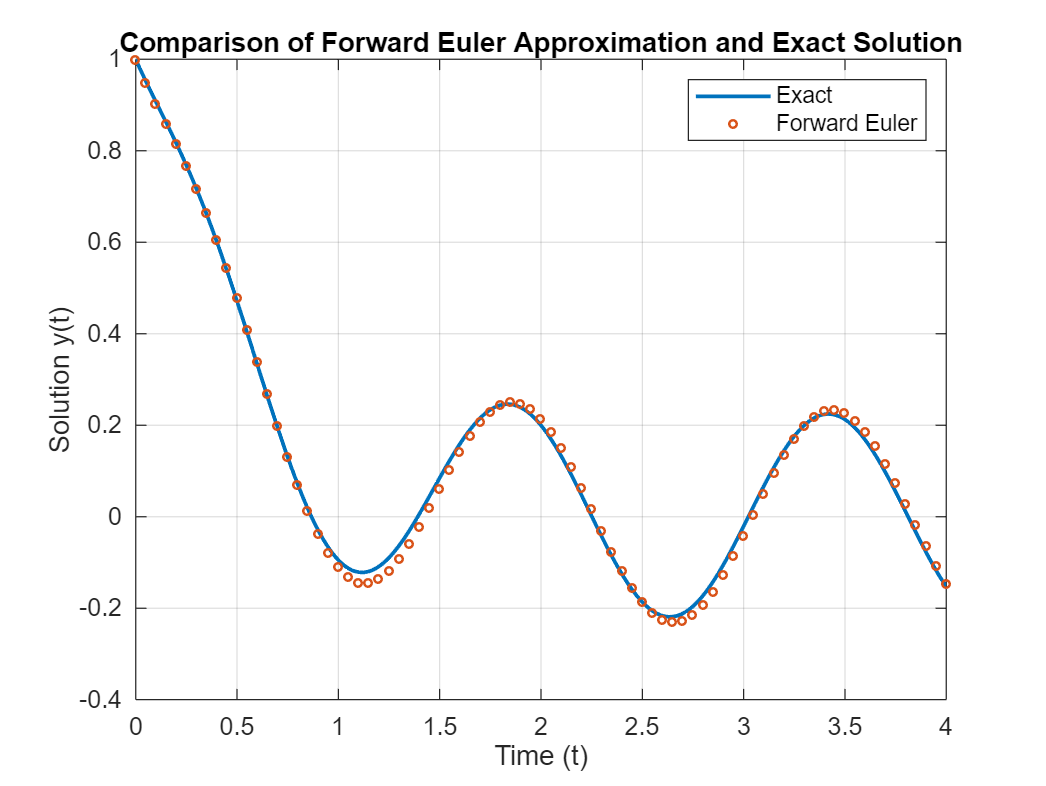

% Forward Euler Method Example
% Solves the ODE: dS/dt = cos(4t) - 2S
% using the Forward Euler method and compares with the exact solution.

% Setup
clear; close all; clc;

s0 = 1;             % Initial condition y(0)
h  = 0.05;           % Step size (try 1, 0.2, or 0.1)
tfinal = 4;  % Final Time
t  = 0:h:tfinal;         % Time vector from 0 to 4 seconds

s = zeros(size(t)); % Preallocate memory for solution
s(1) = s0;          % Apply initial condition

% Define ODE as anonymous function: dy/dt = cos(4t) - 2y
f = @(t, y) cos(4*t) - 2*y;

% Forward Euler Integration
%     Euler uses this formula
%     New Value = Old Value + (Derivative * h)

for ii = 1:length(t) - 1
    s(ii + 1) = s(ii) + h * f(t(ii), s(ii));
    % f(t,y) means the derivative from the differential equation.
    % We use this because we chose to define it as an anonymous fucntion
    % This is the format for anonymous fucntions!
end

% Exact Solution
% Analytical solution for comparison
y_exact = @(t) (s0-1/10)*exp(-2*t) +1/5 * sin(4*t) + 1/10 *cos(4*t);

% The exact solution is the mathematical solution you get by solving the differential equation analytically, 
% rather than approximating it numerically.


% Plot Results
figure;
tt = linspace(0, tfinal, 200);   % Smooth time vector for exact solution

plot(tt, y_exact(tt), 'LineWidth', 1.5);  % Exact solution
hold on;
plot(t, s, 'o', 'MarkerSize', 3, 'LineWidth', 1);
hold off;

xlabel('Time (t)');
ylabel('Solution y(t)');
legend('Exact', 'Forward Euler', 'Location', 'northeast');
title('Comparison of Forward Euler Approximation and Exact Solution');
grid on;

idx = abs(t - 2) < 1e-3   % Find index closest to t = 2

idx = 1×81 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0


err = abs(s(idx) - y_exact(2));      % Absolute error at t = 2
fprintf('Absolute error at t = 2: %.6f\n', err);

Absolute error at t = 2: 0.015195


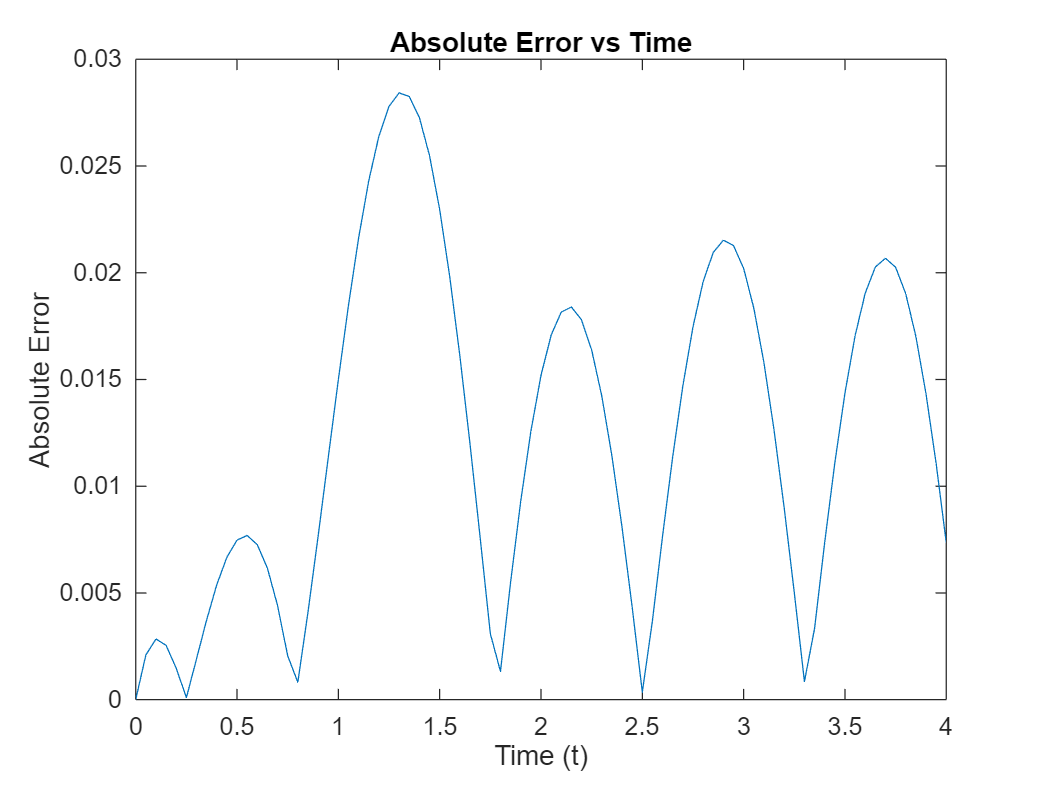

max_error = abs(s - y_exact(t));
figure
plot(t, max_error)
title('Absolute Error vs Time')
xlabel('Time (t)');
ylabel('Absolute Error');

### Error Propagation in Euler’s Forward Method

#### Example 3

Euler’s Forward Method is an explicit method. Explicit methods are very easy to implement, however, the drawback arises from the limitations on the time step size to ensure *numerical stability.*

***Forward Euler uses the previous approximate value to calculate the next value, so an error made at one step can carry forward into later steps***

Plot the derivative approximation of the function from t = 5 to 10:


$$\frac{\textrm{ds}}{\textrm{dt}}=e^t \left(8\;\cos \left(8t\right)+\sin \left(8t\right)\right)$$


Remember that we can approximate the first derivative using the Forward Euler Method


$$f\left(t_k ,y_k \right)=\frac{y_{k+1} -y_k }{h}$$


Discretize our differential equation:


$$\frac{\left(S_{i+1} -S_i \right)}{h}=e^{t_i } \left(8\;\cos \left(8t_i \right)+\sin \left(8t_i \right)\right)$$


Solve for $S_{i+1}$


$$S_{i+1} =S_i +h*\left(e^{t_i } \left(8\;\cos \left(8t_i \right)+\sin \left(8t_i \right)\right)\right)$$


Notice how $\left(e^{t_i } \left(8\;\cos \left(8t_i \right)+\sin \left(8t_i \right)\right)\right)$ is just our$f{\left(t_k ,y_k \right)}$


$$S_{i+1} =S_i +h*f\left(t_i ,S_i \right)$$


Where y(0)=0, use step size h = .2

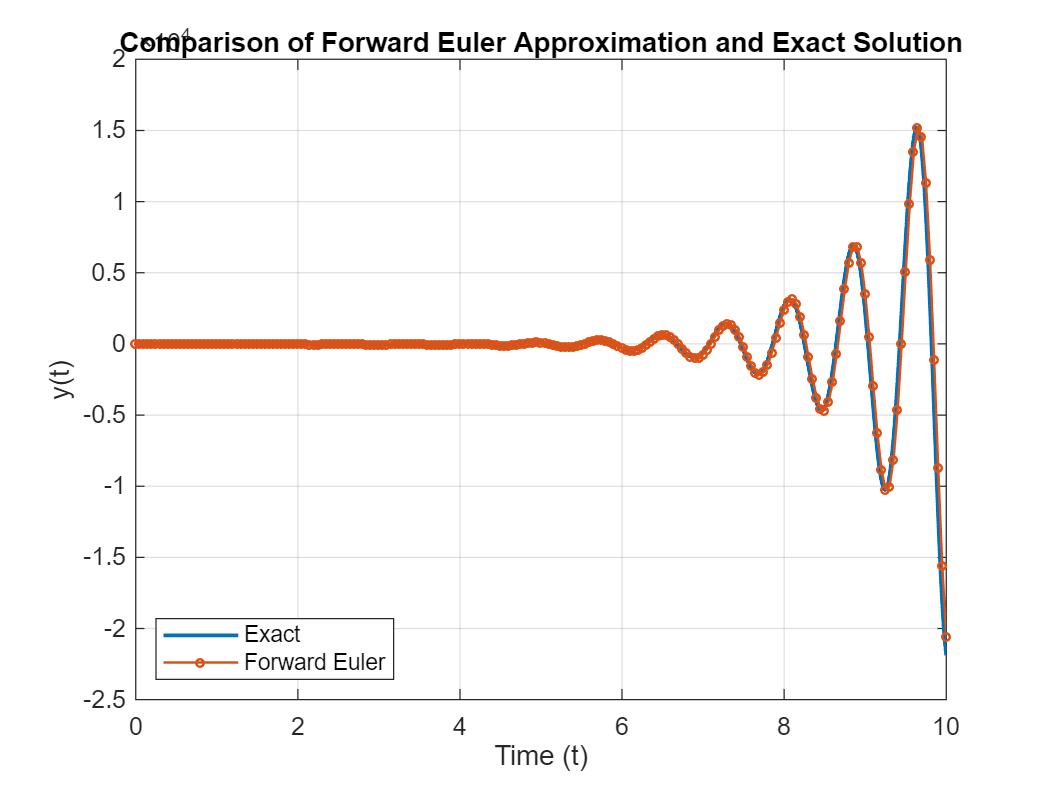

%% Forward Euler Method Example 2
% Solves the ODE: dy/dt = e^t * (8*cos(8t) + sin(8t))
% using the Forward Euler method and compares with the exact solution:
%     y(t) = e^t * sin(8t) + 4
%     y(0) = 0

%% Setup
clear; close all; clc;

s0 = 0;               % Initial condition y(0) = 0
h  = 0.05;% Step size (try 0.2, 0.1, or 0.05)
t  = 0:h:10;          % Time vector from 0 to 10

s_For = zeros(size(t));   % Preallocate memory for solution
s_For(1) = s0;            % Apply initial condition

% Define ODE as an anonymous function
f = @(t, y) exp(t) .* (8*cos(8*t) + sin(8*t));

%% Forward Euler Integration
for ii = 1:length(t) - 1
    s_For(ii + 1) = s_For(ii) + h * f(t(ii), s_For(ii));
end

%% Exact Analytical Solution
y_exact = @(t) exp(t) .* sin(8*t) + 4;

%% Plot Results
figure;
tt = linspace(min(t), max(t), 10000);  % Smooth time vector for exact solution

plot(tt, y_exact(tt), 'LineWidth', 1.5);           % Exact solution
hold on;
plot(t, s_For, '-o', 'MarkerSize', 3, 'LineWidth', 1); % Forward Euler result
hold off;
unstable_zoom=false;
if unstable_zoom
    xlim([8 10]);  % Focus on later portion of the time range
else
    xlim([0 10]);  % Focus on whole time range
end
xlabel('Time (t)');
ylabel('y(t)');
legend('Exact', 'Forward Euler', 'Location', 'southwest');
title('Comparison of Forward Euler Approximation and Exact Solution');
grid on;


% Error Evaluation at Specific Time
t_eval = 10;                                % Time to evaluate error
idx = find(abs(t - t_eval) < 1e-12, 1);     % Index closest to t = 10
err = abs(s_For(idx) - y_exact(t_eval));    % Absolute error
fprintf('Absolute error at t = %.2f: %.6e\n', t_eval, err);

Absolute error at t = 10.00: 1.309672e+03


Why is there drift? Note that because we carry with us the previous value, $S_{i-1}$ at each iteration, our error compounds in the next step, $S_{i+1}$.

Notes on Error Propagation

- Since the exponential term exp(t) amplifies values with time, numerical errors also grow roughly exponentially.

- Reducing the step size h will decrease the global error linearly, $O\left(h\right)$, but may not prevent exponential growth if the ODE itself is unstable/chaotic/stiff.

- Approximation: Euler uses a straight line to estimate a curved solution.

- Step size: With h=0.2h=0.2, each step may miss changes in the curve.

- Error carries forward: Each new step uses the previous approximate value, so errors accumulate.

- Exponential growth: The term etet makes the derivative grow larger over time, increasing the potential error.

- Result: The numerical solution gradually drifts away from the exact solution

#### Stiffness

Stiffness is characterized in terms of the behavior of an explicit method (like forward Euler) on a given problem. A initial value problem (IVP) is stiff in some interval [0, Tf] if the step size needed to maintain stability is much smaller than that needed to meet the accuracy requirements. 

In order words, a stiff system is one that changes rapidly and in order to capture this behavior properly you need a small time-step depending upon how quickly the system changes.

Stiffness is a property of a differential equation that makes it difficult to solve numerically because the time step required for stability is much smaller than the time step required for accuracy.

Where h = time step.

- A large time step means fewer calculations, so the solution is faster to compute.

- A small time step means more calculations, but it can give better accuracy and improve stability.

For stiff problems, you may be forced to use a very small time step, even when the solution itself appears to change slowly.

 Stiffness is not simply about a solution changing rapidly. It is about the numerical method being forced to take small steps to remain stable.

Small Reminder :

- Accuracy: How close is the numerical solution to the true solution?

- Stability: Do numerical errors remain controlled, or do they grow uncontrollably?

## How do we deal with stiff problems?

Two common approaches are:

- Explicit methods: Forward Euler and explicit Runge–Kutta methods. These are often efficient for non-stiff problems but can require very small time steps for stiff problems.

- Implicit methods: Backward Euler and certain implicit Runge–Kutta methods. These generally have better stability properties for stiff problems, allowing larger time steps in many cases.

#### Euler’s Backward Method

The forward method computes the approximations using:


$$y_{k+1} =y_k +f{\left(t_k ,y_k \right)}h$$


- yk� is the value we already know.

- hh is the time step.

- f(tk,yk)f(tk�,yk�) is the slope at the current point.

- yk+1yk+1� is the next value we want to calculate.

A variation is Euler’s Backward Method, which uses:


$$y_{k+1} =y_k +f{\left(t_{k+1} ,y_{k+1} \right)}h$$



$$\frac{dy}{dt}=f{\left(t,y\right)},\ \ y{\left(t=0\right)}=y_0$$


Notice the difference: yk+1yk+1� appears on both sides of the equation.

We know yk� and h, but we don't know yk+1. We also cannot evaluate the slope f(tk+1,yk+1)until we know that next value.

This method has increased stability over the forward method.

The equation is called “implicit” because the value we are searching for, $y_{k+1}$, is expressed in terms of yet unknown quantities, $f{\left(t_{k+1} ,y_{k+1} \right)}$.

Therefore, we must solve for $f{\left(t_{k+1} ,y_{k+1} \right)}$.

Recall backward difference approximation:


$$\frac{\textrm{dy}}{\textrm{dt}}\cong \frac{y_k -y_{k-1} }{h}$$


Discretize  $\frac{\textrm{dy}}{\textrm{dt}}$.


$$\frac{y_k -y_{k-1} }{h}=f{\left(t_k ,y_k \right)}$$


In MATLAB, we can't have an index that starts at 0 go negative so replace shift k forward by 1:


$$\frac{y_{k+1} -y_k }{h}=f{\left(t_{k+1} ,y_{k+1} \right)}$$


Now solve for $y_{k+1}$, the next data point which we want


$$y_{k+1} =y_k +f{\left(t_{k+1} ,y_{k+1} \right)}h$$


Now you might rightly ask, what good does this expression do? To compute the unknown $y_{k+1}$, you need to already know $y_{k+1}$ to use it. But how can you use $y_{k+1}$ if it’s the unknown you are solving for?

The answer is that you can turn the equation into a root-finding problem. Meaning:


$$y_k +f{\left(t_{k+1} ,y_{k+1} \right)}h-y_{k+1} =0$$


We know almost the entire equation except for $y_{k+1}$, if we adjust that number we should be able to find the optimum value that sets the equation to 0, meaning we found the **root**.

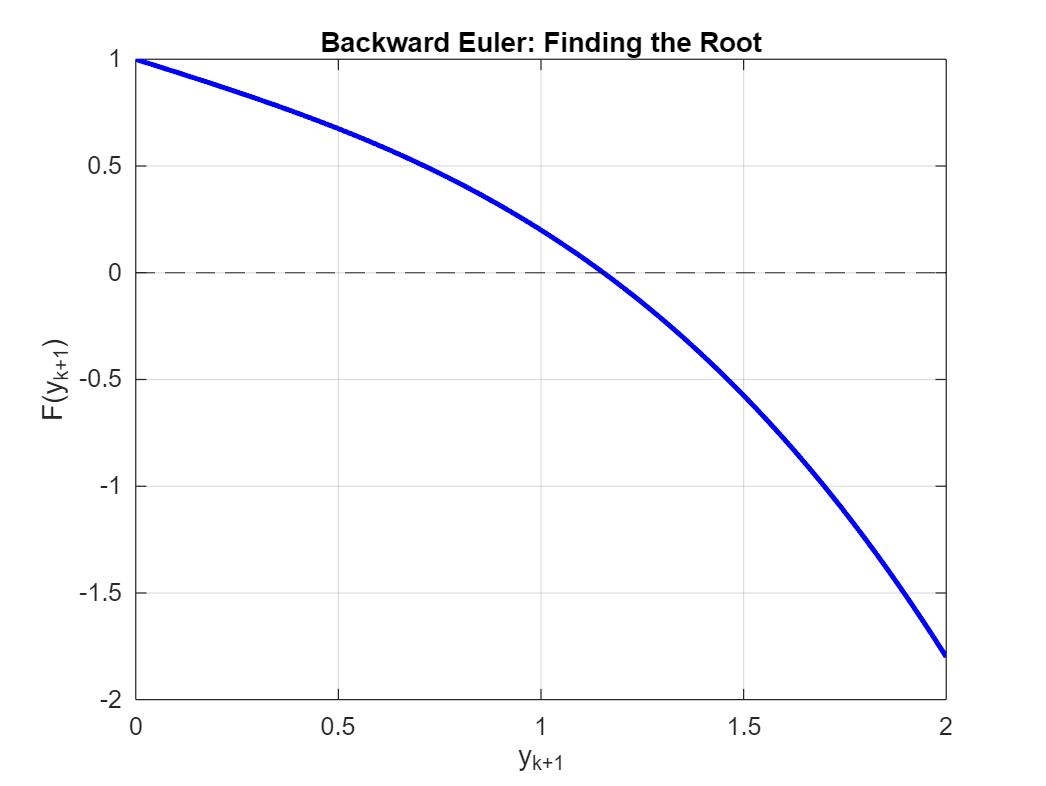

% Root finding for Euler's Backward Method
clear; clc; close all;

yk = 1;
h = 0.2;

% Nonlinear differential equation: dy/dt = -y^3 + 2*y
f = @(t,y) -y.^3 + 2*y;  % This not y, this is y' !!!

% Residual equation: F(y_{k+1}) = 0
F = @(y) yk + h*f(0,y) - y;

y = linspace(0, 2, 500); % smooth it, generates 500 equally spaced trial values between 0 and 2

figure;
plot(y, F(y), 'b-', 'LineWidth', 2);
hold on;
yline(0, 'k--');
xlabel('y_{k+1}');
ylabel('F(y_{k+1})');
title('Backward Euler: Finding the Root');
grid on;

#### Example 2 revisited

For  the function:


$$\frac{\textrm{ds}}{\textrm{dt}}=e^t \left(8\;\cos \left(8t\right)+\sin \left(8t\right)\right)$$


Where y(0)=0, and step size h= .1.

Plot the derivative approximation of the function from t = 5 to 10.

Use the Implicit (backward) Euler Method.

Remember that we can approximate the first derivative using the Backward Euler Method


$$\frac{y_k -y_{k-1} }{h}=f{\left(t_k ,y_k \right)}$$


Shift indices by 1


$$\frac{y_{k+1} -y_k }{h}=f{\left(t_{k+1} ,y_{k+1} \right)}$$


Discretize our differential equation:


$$\frac{\left(S_{i+1} -S_i \right)}{h}=e^{t_{i+1} } \left(8\;\cos \left(8t_{i+1} \right)+\sin \left(8t_{i+1} \right)\right)$$


Solve for $S_{i+1}$


$$S_{i+1} =S_i +h*\left(e^{t_{i+1} } \left(8\;\cos \left(8t_{i+1} \right)+\sin \left(8t_{i+1} \right)\right)\right)$$


Notice how $\left(e^{t_{i+1} } \left(8\;\cos \left(8t_{i+1} \right)+\sin \left(8t_{i+1} \right)\right)\right)$ is just our$f{\left(t_{k+1} ,y_{k+1} \right)}$


$$S_{i+1} =S_i +h*f{\left(t_{i+1} ,S_{i+1} \right)}$$


To solve set the equation equal to zero and turn it into a root finding problem


$$0=S_i +h*f{\left(t_{i+1} ,S_{i+1} \right)}-S_{i+1}$$


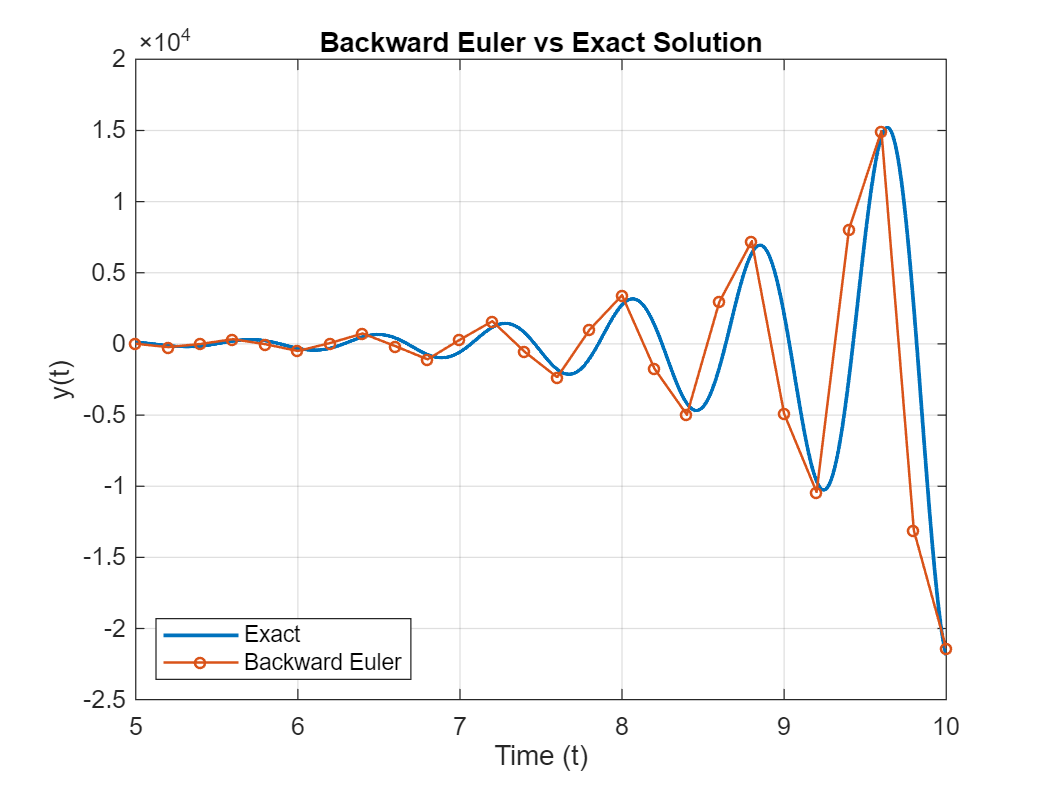

% Backward Euler Method Example
% Solves the ODE: dy/dt = e^t * (8*cos(8*t) + sin(8*t))
% using the Backward Euler method and compares with the exact solution:
%    y(t) = e^t * sin(8*t) + 4

%This example DOES NOT depend on y!

% Setup
clear; close all; clc;

s0 = 0;               % Initial condition y(0) = 0
h  = 0.2;             % Step size (try 0.2, 0.1, 0.05)
t  = 0:h:10;          % Time vector from 0 to 10

% Define ODE as an anonymous function: dy/dt = f(t,y)
f = @(t, y) exp(t) .* (8*cos(8*t) + sin(8*t));

% Exact solution for comparison / initial guesses
y_exact = @(t) exp(t) .* sin(8*t) + 4;

% Backward Euler Integration (implicit)
% Backward Euler update: Y = s_n + h * f(t_{n+1}, Y)
% Solve for Y at each step using fzero.

s_Back = zeros(size(t));   % Preallocate memory for solution, >> y_n
s_Back(1) = s0;            % Apply initial condition >> y_n+1

for ii = 1:length(t)-1
    % Root function for fzero: g(Y) = sn + h*f(tn1, Y) - Y
    g = @(Y) s_Back(ii) + h * f(t(ii+1), Y) - Y; 
    % Basically:  y_n+1 = y_n + h* f(t_n+1 , y_n+1)
    %             t(ii+1) >> t_n+1
    
    % Solve implicit problem with fzero
    s_Back(ii+1) = fzero(g, s_Back(ii)); 
    % fzero finds a value that makes a function equal to zero.
    % We want to find Y such that g(Y)=0.
    % Basically: fzero(root_function, initial_guess)
end

%% Plot Results
figure;
tt = linspace(min(t), max(t), 10000);  % smooth time vector for exact solution
plot(tt, y_exact(tt), 'LineWidth', 1.5);   % exact solution
hold on;
plot(t, s_Back, '-o', 'MarkerSize', 4, 'LineWidth', 1);  % Backward Euler result
hold off;

xlim([5 10]);   % focus on later portion as before
xlabel('Time (t)');
ylabel('y(t)');
legend('Exact', 'Backward Euler', 'Location', 'southwest');
title('Backward Euler vs Exact Solution');
grid on;

%% Error Evaluation at Specific Time
t_eval = 10;                                 % time to evaluate error
idx = find(abs(t - t_eval) < 1e-12, 1);      % index closest to t = 10
err_BE = abs(s_Back(idx) - y_exact(t_eval)); % absolute error
fprintf('Backward Euler absolute error at t = %.2f: %.6e\n', t_eval, err_BE);

Backward Euler absolute error at t = 10.00: 5.069246e+02


Notes on Backward Euler

- Backward Euler is implicit and stable: it is better for stiff problems and problems with rapidly growing/decaying modes than Forward Euler.

- Each step requires solving a nonlinear equation; fzero (or fsolve) is commonly used. A good initial guess (previous step or exact if known ) speeds convergence.

- Backward Euler has global accuracy O(h) (same order as Forward Euler), but often much better stability properties for stiff/unstable ODEs.

- **Forward Euler** extrapolates forward using the current slope → tends to overshoot and amplify errors.

- **Backward Euler** instead *implicitly* uses the future slope (requires solving for $y_{k+1}$) → naturally damps out oscillations and numerical instabilities.

TIP: [Fzero](https://www.mathworks.com/help/matlab/ref/fzero.html)

#### Example 3

For  the function:


$$\frac{\textrm{dy}}{\textrm{dt}}=e^{-y} \left(2t-4\right)$$


Use the Implicit (backward) Euler Method to find $y\left(t\right)$ and plot it for t between 5 and 8 with y(5)=0.

Compare it against the explicit (forward) Euler Method.

Forward Euler will always have the discretized form


$$y_{k+1} =y_k +f{\left(t_k ,y_k \right)}h$$


So we can match it with our information


$$y_{k+1} =y_k +e^{-y_i } \left(2t_i -4\right)h$$


Backward Euler will also always have the same form


$$y_k +f{\left(t_{k+1} ,y_{k+1} \right)}h-y_{k+1} =0$$


So we can match it with our information


$$y_k +e^{-y_{i+1} } \left(2t_{i+1} -4\right)h-y_{k+1} =0$$


For reference the exact analytical solution is:


$$y\left(t\right)=\ln \left(t^2 -4t-4\right)$$


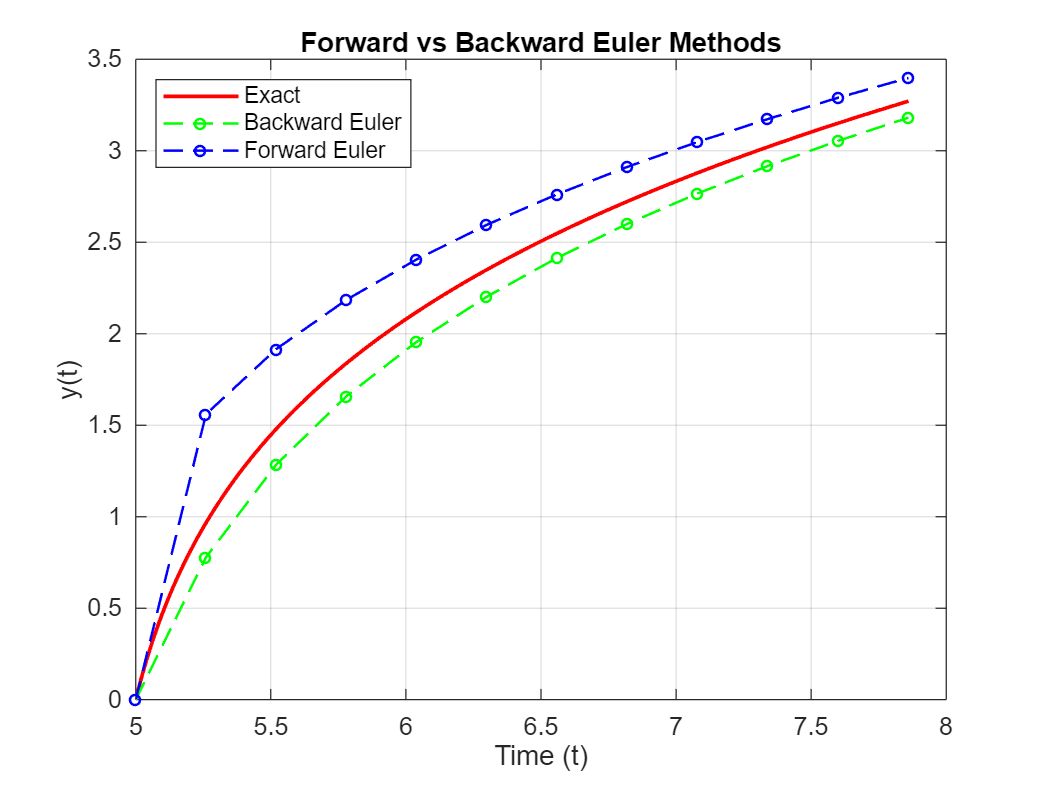

% Forward and Backward Euler Comparison Example
% Solves the ODE: dy/dt = e^{-y} * (2t - 4)
% using both Forward Euler and Backward Euler methods,
% and compares with the exact analytical solution:
%     y(t) = ln(t^2 - 4t - 4)

%This example DOES depend on y!


% Setup
clear; close all; clc;

s0 = 0;               % Initial condition y(5) = 0
h  = 0.26;            % Step size (try 0.25, 0.1, 0.05)
t  = 5:h:8;           % Time vector from 5 to 8

%Set up for BOTH fowards and backwards

s_For  = zeros(size(t));   % Preallocate memory for Forward Euler
s_Back = zeros(size(t));   % Preallocate memory for Backward Euler

%Both methods start with the same initial value:
s_For(1)  = s0;            % Apply initial condition
s_Back(1) = s0;            % Apply initial condition




% Define ODE as an anonymous function: dy/dt = f(t, y)
f = @(t, y) exp(-y) .* (2*t - 4);

% Exact solution for comparison
y_exact = @(t) log(t.^2 - 4.*t - 4);

%% Forward and Backward Euler Integration
for ii = 1:length(t) - 1
    current_t   = t(ii);
    future_t  = t(ii+1); % the time you want to calculate the solution for.

    % Forward Euler (explicit)
    s_For(ii+1) = s_For(ii) + h * f(current_t, s_For(ii));

    % Backward Euler (implicit)
    % Solve implicit equation: Y = s_n + h*f(t_{n+1}, Y)
    g = @(Y) s_Back(ii) + h * f(future_t, Y) - Y;  % root function
    s_Back(ii+1) = fzero(g, s_Back(ii));      % use previous step as initial guess
end

% Plot Results
figure;
tt = linspace(min(t), max(t), 1000);  % Smooth time vector for exact curve
plot(tt, y_exact(tt), 'r-', 'LineWidth', 1.5);       % Exact solution
hold on;
plot(t, s_Back, 'g--o', 'MarkerSize', 4, 'LineWidth', 1);  % Backward Euler
plot(t, s_For,  'b--o', 'MarkerSize', 4, 'LineWidth', 1);  % Forward Euler
hold off;

xlabel('Time (t)');
ylabel('y(t)');
legend('Exact', 'Backward Euler', 'Forward Euler', 'Location', 'northwest');
title('Forward vs Backward Euler Methods');
grid on;

% Error Evaluation at Final Time     
t_eval = 8;                                  % Evaluate at final time
idx = find(abs(t - t_eval) < 1e-3, 1);      % Index closest to t_eval

err_FE = abs(s_For(idx)  - y_exact(t_eval)); % Forward Euler error
err_BE = abs(s_Back(idx) - y_exact(t_eval)); % Backward Euler error

fprintf('Absolute error at t = %.2f:\n', t_eval);

Absolute error at t = 8.00:


fprintf('   Forward Euler  : %.6e\n', err_FE);

   Forward Euler  : 


fprintf('   Backward Euler : %.6e\n', err_BE);

   Backward Euler : 


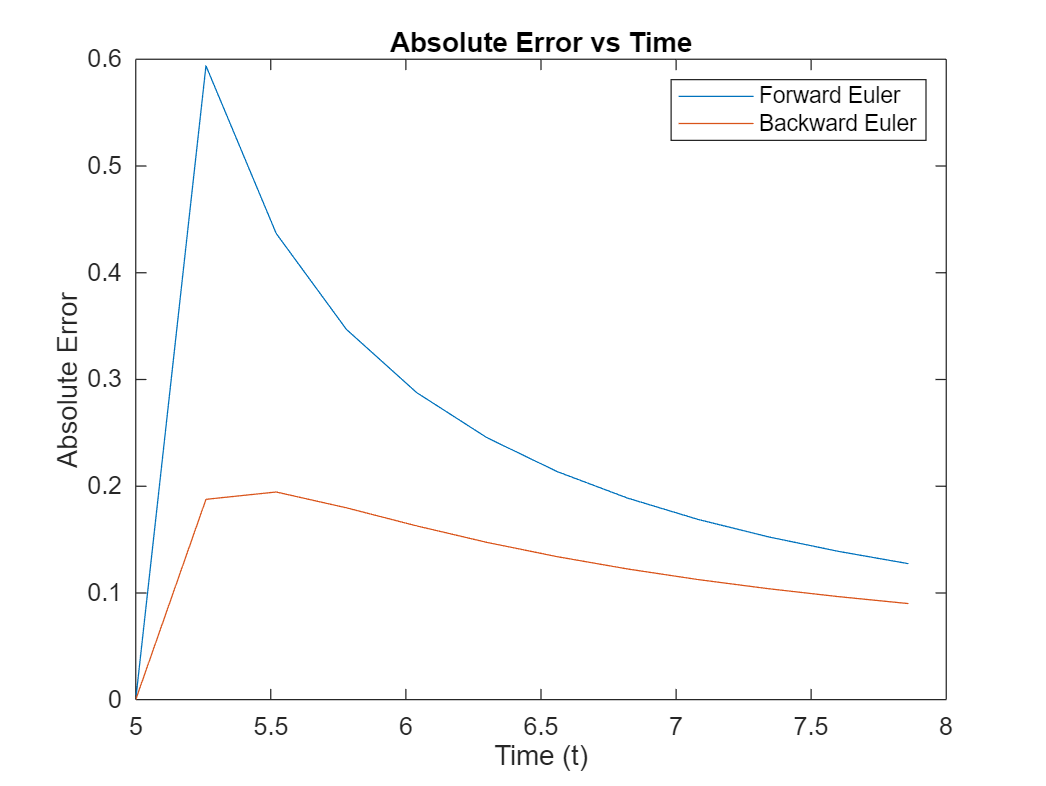

% Error over Time
err_FE = abs(s_For  - y_exact(t)); % Forward Euler error
err_BE = abs(s_Back - y_exact(t)); % Backward Euler error
figure
plot(t, err_FE)
hold on
plot(t, err_BE)
title('Absolute Error vs Time')
legend('Forward Euler','Backward Euler')
xlabel('Time (t)');
ylabel('Absolute Error');

Notes on Method Behavior

- Forward Euler is explicit (easy to compute) but conditionally stable.

- Backward Euler is implicit (requires solving for Y each step) but stable, making it better for stiff or rapidly changing systems.

- Both methods are first-order accurate: global error = $O\left(h\right)$.

#### Convergence

Show that the absolute error of the approximation of both Forward and Backward Euler Methods, at y(3), converges with decreasing h:


$$\frac{\textrm{dy}}{\textrm{dt}}=e^{-t} \left(8\;\cos \left(8t\right)-\sin \left(8t\right)\right)$$


knowing that y(0)=4 and that the true solution is


$$y\left(t\right)=\sin \left(8t\right)e^{-t} +4$$


To make it easier let's first do it for Forward Method

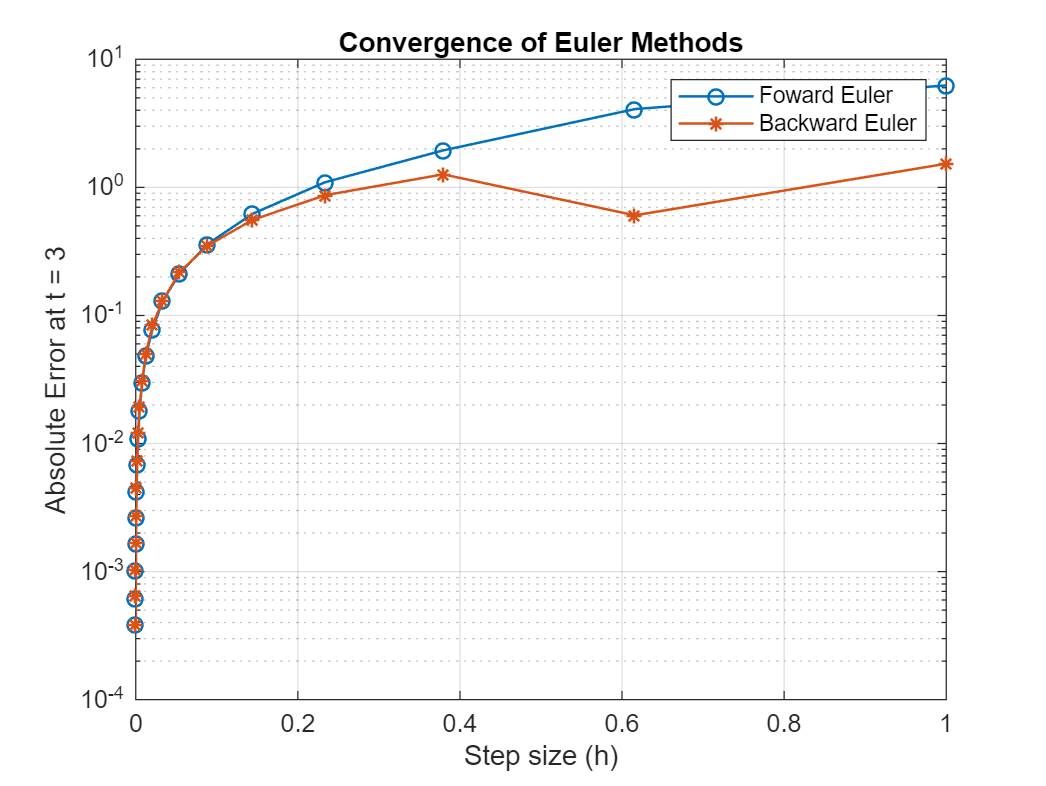

% Forward Euler Convergence Test
% ODE: dy/dt = e^(-t)*(8*cos(8*t) - sin(8*t))
% Exact: y(t) = e^(-t)*sin(8*t) + 4

clear; clc; close all;

% Step sizes to test
h_values = logspace(-4, 0, 20);  

% Preallocation
errors_forward = zeros(1, length(h_values));
errors_backward = zeros(1, length(h_values));

% True solution and ODE
y_true = @(t) exp(-t).*sin(8*t) + 4;
f = @(t, y) exp(-t).*(8*cos(8*t) - sin(8*t));

% Initial condition and end time
y0 = 4;
t_end = 3;
y_exact = y_true(t_end);

% Loop over different step sizes
for ii = 1:length(h_values)
    h = h_values(ii);
    t = 0:h:t_end;
    % Preallocate solution vectors
    y_forward = zeros(1, length(t));
    y_backward = zeros(1, length(t));
    % Set initial conditions
    y_forward(1) = y0;
    y_backward(1) = y0;

    % Forward Euler Method
    for jj = 1:length(t)-1
        y_forward(jj+1) = y_forward(jj) + h * f(t(jj), y_forward(jj));
    end

    % Backward Euler Method (implicit)
    for jj = 1:length(t)-1
        y_backward(jj+1) = fzero(@(Y) y_backward(jj) + (f(t(jj+1),Y))*h - Y, y_backward(jj));
    end
    % Absolute error at t = 3 forwards method
    errors_forward(ii) = abs(y_exact - y_forward(end));
    % Absolute error at t = 3 for backwards methods
    errors_backward(ii) = abs(y_exact - y_backward(end));
end

% Plot convergence
semilogy(h_values, errors_forward, '-o', 'LineWidth', 1);
hold on
semilogy(h_values, errors_backward, '-*','LineWidth', 1);
grid on;
xlabel('Step size (h)');
ylabel('Absolute Error at t = 3');
title('Convergence of Euler Methods');
legend('Foward Euler','Backward Euler');

TIP: [logspace](https://www.mathworks.com/help/matlab/ref/logspace.html?s_tid=doc_ta)

TIP: [semilogx](https://www.mathworks.com/help/matlab/ref/semilogx.html?s_tid=doc_ta), [semilogy](https://www.mathworks.com/help/matlab/ref/semilogy.html), [loglog](https://www.mathworks.com/help/matlab/ref/loglog.html)

#### Break the Method - Explore Stability Limits: Nonlinear Growth

Let's investigate a logistic-like ODE (nonlinear growth) that grows quickly and can become unstable for large step sizes in Forward Euler.


$$\frac{\textrm{dP}}{\textrm{dt}}=\textrm{rP}\left(1-\frac{P}{K}\right)$$



$$\begin{array}{l}
r=\textrm{Growth}\;\textrm{Rate}\\
K=\textrm{Carrying}\;\textrm{Capacity}\\
P=\textrm{Population}\\
t=\textrm{Time}
\end{array}$$


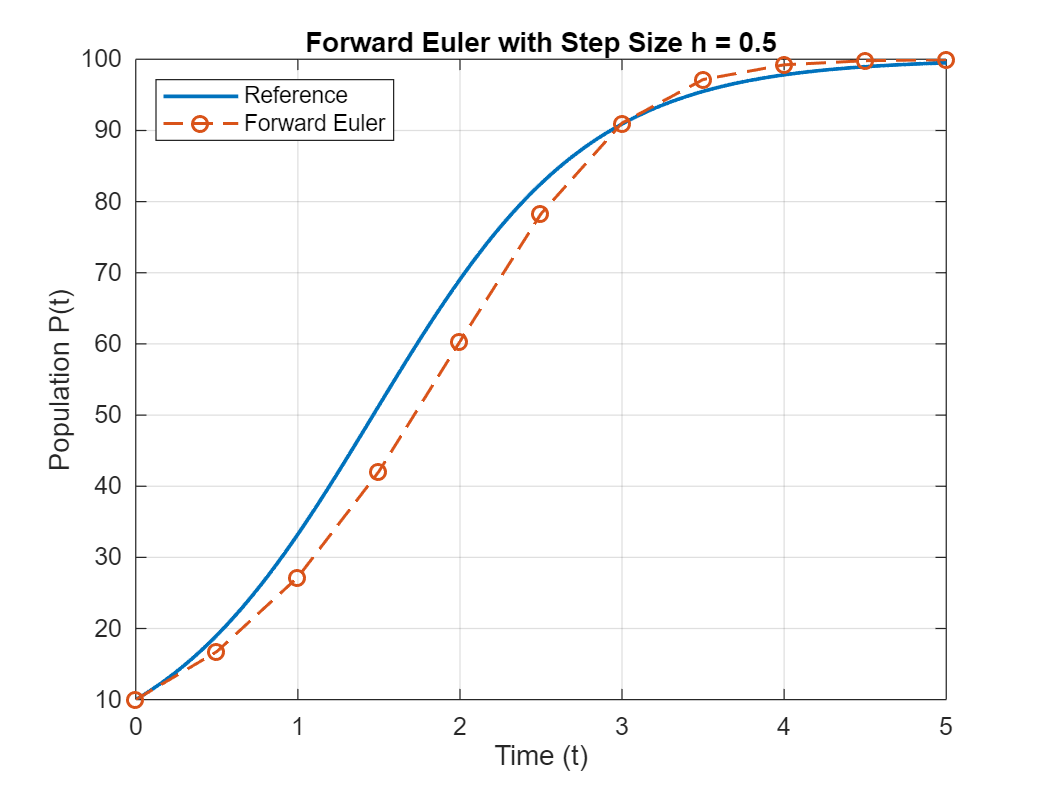

% ODE: dP/dt = r * P * (1 - P/K)
% This represents population growth with a carrying capacity K.
% Large step sizes can cause Forward Euler to produce unrealistic results.

% Parameters
r = 1.5;       % Growth rate
K = 100;       % Carrying capacity
P0 = 10;       % Initial population
t_end = 5;     % Simulation time

% Step size selection 
h  = 0.5;  % Challenging step sizes 

% Time vector
t = 0:h:t_end;

% Preallocate solution
P = zeros(size(t));
P(1) = P0;

% Forward Euler integration
for ii = 1:length(t)-1
    P(ii+1) = P(ii) + h*r*P(ii)*(1 - P(ii)/K);
end

% Exact solution (numerical solution with very small h for reference)
t_fine = linspace(0, t_end, 1000);
P_exact = @(t) K ./ (1 + ((K - P0)/P0)*exp(-r*t));

% Plot results
figure;
plot(t_fine, P_exact(t_fine), 'LineWidth', 1.5); hold on;
plot(t, P, 'o--', 'LineWidth', 1.2, 'MarkerSize', 6);
xlabel('Time (t)');
ylabel('Population P(t)');
legend('Reference','Forward Euler','Location','northwest');
title(sprintf('Forward Euler with Step Size h = %.1f', h));
grid on;

Observe the Forward Euler approximation:

- How does increasing h affect the numerical solution?

- Why does the solution overshoot or oscillate for large h?

- Can you identify a rough "stability limit" for this nonlinear ODE?